% Imperial College London
% 2024-25 MRes in Medical Robotics and Instrumentation
% Coursework 01 - Task 02
% Author: Hongyu Wang

clc;
close all;
clear;

config = initConfig();
robot = initRobot(config);

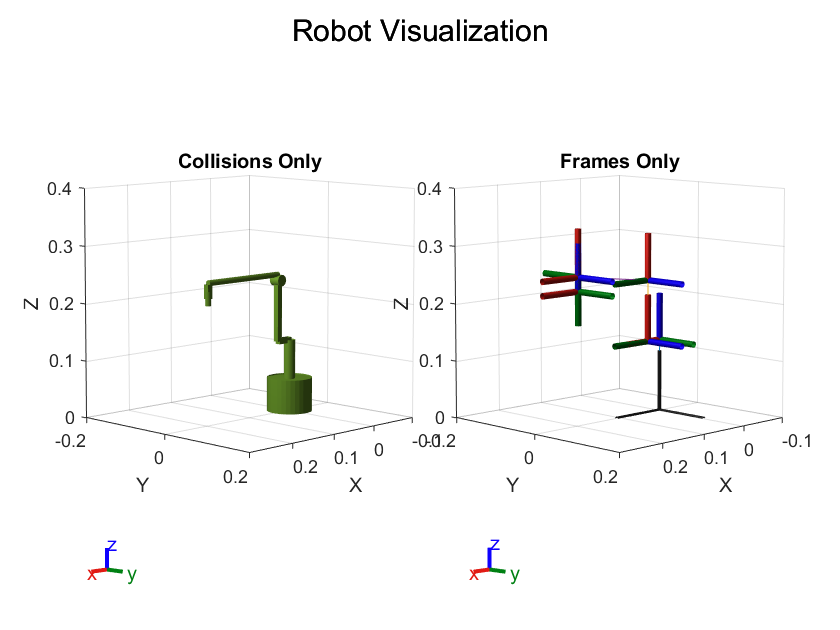

showRobotCollisionsAndFrames(robot, config.home_configuration_matlab');

## Path Planning - Based on CoppeliaSim

% Home Postition --> Offset                 % For CoppeliaSim
PH_COPPELIA = config.home_configuration_coppelia;                             % CoppeliaSim = [0, 0, 0, 0, 0, 0];
P0_COPPELIA = [0, pi/4, pi/5, pi/4, 0, 0];
P1_COPPELIA = [-pi/5, pi/5, -pi/4, pi/2, 0, 0];
P2_COPPELIA = [-pi/2, 0, pi/6, 0, 0, 0];

KEY_POINTS_COPPELIA = [PH_COPPELIA; P0_COPPELIA; P1_COPPELIA; P2_COPPELIA; P0_COPPELIA];
clear PH_COPPELIA P0_COPPELIA P1_COPPELIA P2_COPPELIA;

validateAngles(KEY_POINTS_COPPELIA, config.joint_angle_limits_coppelia);

[LOG INFO] -- Validate Angles...
[LOG INFO] -- All joint angles are within limits.


time_segment_cnt = size(KEY_POINTS_COPPELIA, 1) - 1;
time_segment_len = 5;
time_points = 0:time_segment_len:(time_segment_cnt * time_segment_len);
clear time_segment_cnt time_segment_len;
time_points = calculateOptimalTimeIntervals(KEY_POINTS_COPPELIA, time_points, config.joint_velocity_limits, 2);

[LOG INFO] -- Calculating Optimal Time Intervals...
[LOG INFO] -- Optimal Time Intervals Calculated
[LOG INFO] -- Adjusted Time Points: [0.00, 1.50, 3.99, 6.30, 8.42] 


[q_coppelia, qd_coppelia, qdd_coppelia, time_samples] = generateQuinticPolynomialTrajectory(KEY_POINTS_COPPELIA, time_points);

[LOG INFO] -- Starting Quintic Polynomial Trajectory Generation...
[LOG INFO] -- Quintic Polynomial Trajectory Successfully Generated.


validateAngles(q_coppelia, config.joint_angle_limits_coppelia);

[LOG INFO] -- Validate Angles...
[LOG INFO] -- All joint angles are within limits.


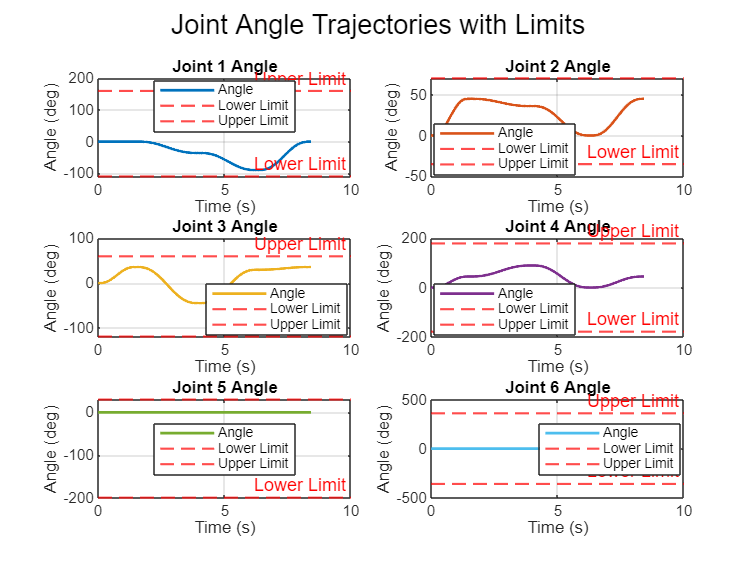

showJointAngleInTrajectory(q_coppelia, config.joint_angle_limits_coppelia,time_samples);

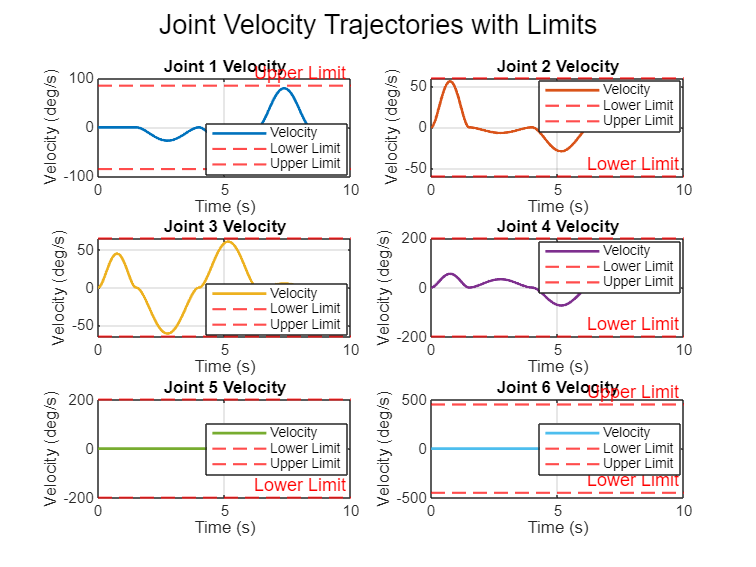

showJointVelocityInTrajectory(qd_coppelia, config.joint_velocity_limits', time_samples);

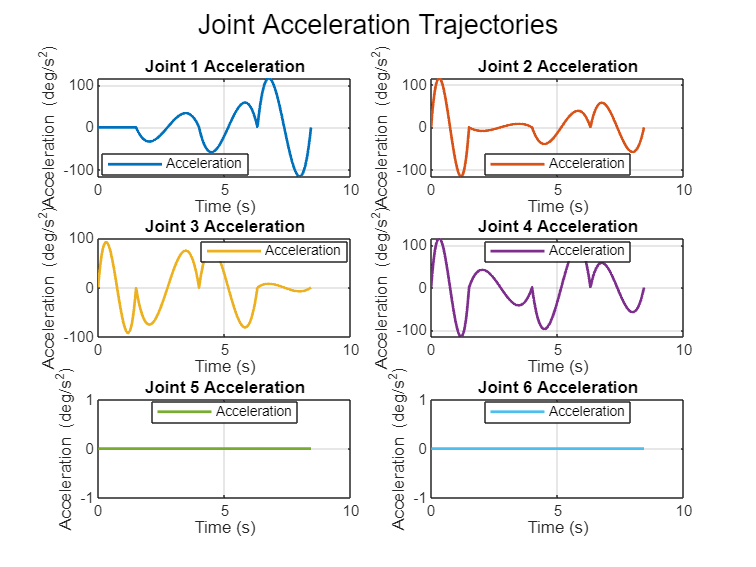

showJointAccelerationInTrajectory(qdd_coppelia, time_samples);

## Save the result in csv

writematrix(q_coppelia, 'Datas/task02_angles.csv');
writematrix(time_samples', 'Datas/task02_times.csv');

## MATLAB Simulation

% Apply offset to trajectory for MATLAB simulation
KEY_POINTS_MATLAB = KEY_POINTS_COPPELIA + (config.home_configuration_matlab - config.home_configuration_coppelia);
key_postition_matlab = zeros(size(KEY_POINTS_MATLAB, 1),3);

for step = 1:size(KEY_POINTS_MATLAB, 1)
    transform = getTransform(robot, KEY_POINTS_MATLAB(step, :)', 'endeffector');
    key_postition_matlab(step, :) = transform(1:3, 4)';
end


q_matlab = q_coppelia + (config.home_configuration_matlab - config.home_configuration_coppelia);
ee_positions_matlab = zeros(size(q_matlab, 1), 3); 

for step = 1:size(q_matlab, 1)
    transform = getTransform(robot, q_matlab(step, :)', 'endeffector');
    ee_positions_matlab(step, :) = transform(1:3, 4)';
end
fprintf('[LOG INFO] -- MATLAB Simulation Complete.\n');

[LOG INFO] -- MATLAB Simulation Complete.


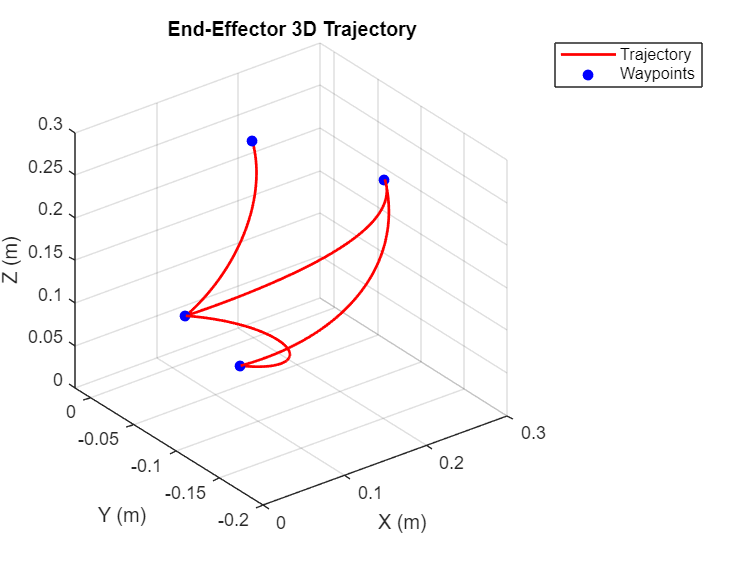

% Plot the 3D trajectory of the end-effector
figure;

plot3(ee_positions_matlab(:, 1), ee_positions_matlab(:, 2), ee_positions_matlab(:, 3), 'r-', 'LineWidth', 1.5);
hold on;
scatter3(key_postition_matlab(:, 1), key_postition_matlab(:, 2), key_postition_matlab(:, 3), 'bo', 'filled');

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('End-Effector 3D Trajectory');
legend('Trajectory', 'Waypoints');
grid on;
hold off;

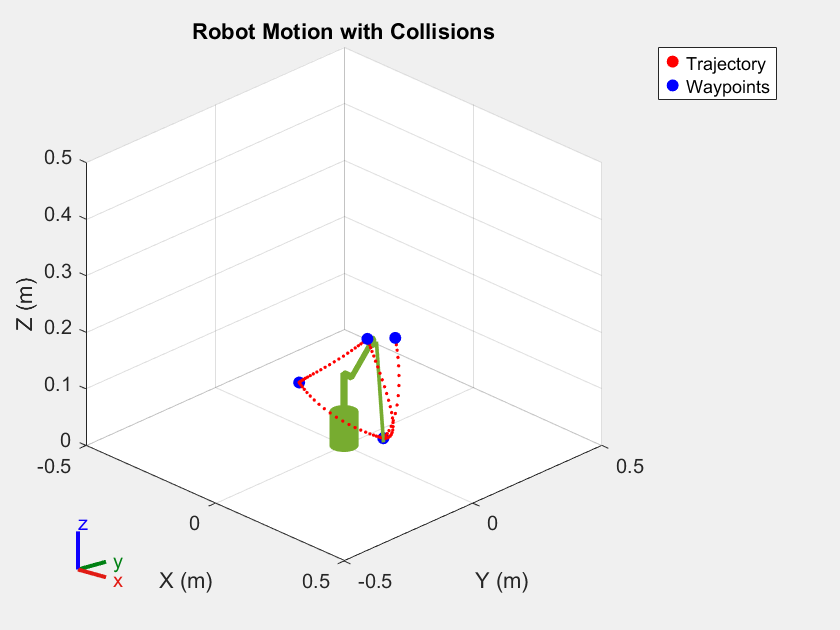

[LOG INFO] -- Simulation complete.


simulateRobotMATLAB(robot, q_matlab,key_postition_matlab, 'collision', 5, true);

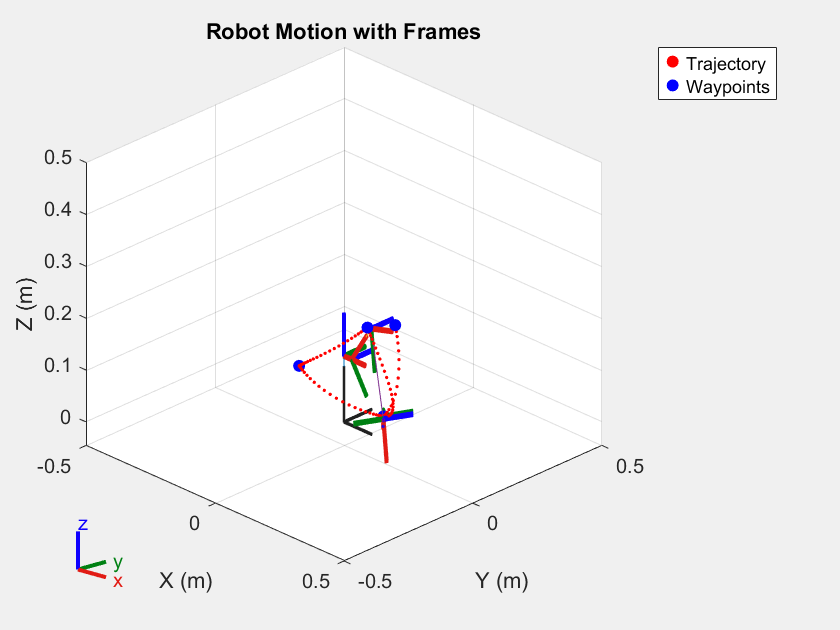

[LOG INFO] -- Simulation complete.


simulateRobotMATLAB(robot, q_matlab, key_postition_matlab,'frame', 5, true);

## CoppeliaSim Using ZeroMQ

HOST = '127.0.0.1'; % CoppeliaSim IP
PORT = 23000;       % Port CoppeliaSim ZeroMQ is listening on

checkCoppeliaSimConnection(HOST, PORT, 5);

[LOG INFO] -- CoppeliaSim Can be Connected
[LOG INFO] -- CoppeliaSim IP Address 127.0.0.1


% Initialize Remote API Client
simClient = RemoteAPIClient();

% Define joint names and end-effector name
jointNames = {'/Mirobot/joint1', '/Mirobot/joint2', '/Mirobot/joint3', ...
              '/Mirobot/joint4', '/Mirobot/joint5', '/Mirobot/joint6'};
eeName = '/Mirobot/Tip';

% Simulate robot in CoppeliaSim
ee_positions_coppelia = simulateRobotCoppeliaSim(q_coppelia,  time_samples, simClient, jointNames, eeName);

[LOG INFO] -- Connecting to CoppeliaSim...
[LOG INFO] -- Simulation started successfully.
[LOG INFO] -- Executing trajectory and recording end-effector positions...
[LOG INFO] -- Simulation stopped.
[LOG INFO] -- End-effector positions recorded.


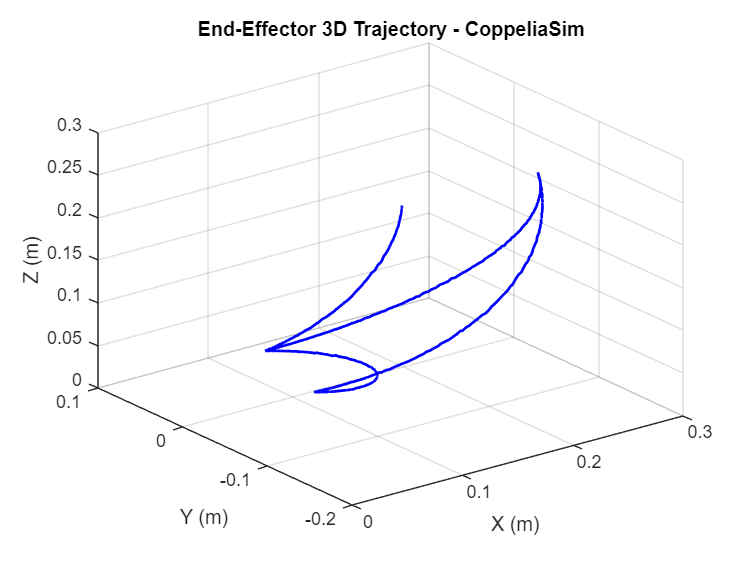

% Plot the 3D trajectory of the end-effector
figure;
plot3(ee_positions_coppelia(:, 1), ee_positions_coppelia(:, 2), ee_positions_coppelia(:, 3), 'b-', 'LineWidth', 1.5);
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('End-Effector 3D Trajectory - CoppeliaSim');
grid on;

## Compare MATLAB and CoppeliaSim

[LOG INFO] -- ERROR INITIAL: [-0.0004, 0.0000, -0.0407] 
[LOG INFO] -- ERROR AVG: 0.0393 m
[LOG INFO] -- ERROR STD: 0.0012 m
[LOG INFO] -- ERROR MAX: 0.0429 m
[LOG INFO] -- ERROR MIN: 0.0355 m


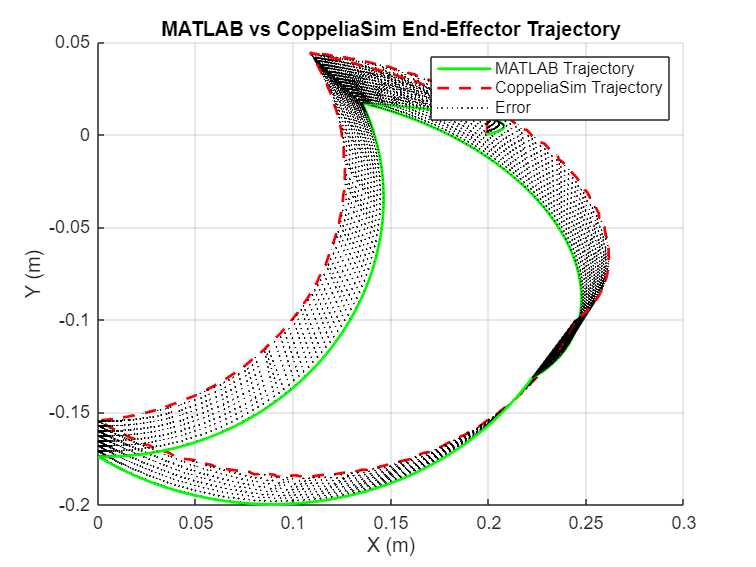

evaluateTrajectoryCoppeliaAndMATLAB(ee_positions_coppelia, ee_positions_matlab);